%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms t u alpha omega v_l v_r d

%% Robot Config
alpha = 1/3;
d = 0.235; % m

U_RANGE = [0 3.2];
T_RANGE = U_RANGE ./ alpha;
N = 50;

u = t .* alpha;

us = linspace(U_RANGE(1), U_RANGE(2), N)';
ts = us ./ alpha;

assume(t, {'real', 'positive'}) % parameter t should be real
assume(u, {'real', 'positive'}) % parameter a should be real
assume(omega, 'real')
assume(v_l, 'real')
assume(v_r, 'real')
% assumeAlso(u >= 0)
% assumeAlso(u <= 3.2)

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4 * (0.3960 * cos(2.65 * (u + 1.4)));
rj=4 * (-0.99 * sin(u + 1.4));
rk=0*u;
r=[ri,rj,rk]

$$r = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,t}{60}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$


%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,t);
v = dr

$$v = \left(\begin{array}{ccc} -\frac{1749\,\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)}{1250} & -\frac{33\,\cos\left(\frac{t}{3}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

speed = norm(v)

$$speed = \sqrt{\frac{3059001\,{\left|\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{1089\,{\left|\cos\left(\frac{t}{3}+\frac{7}{5}\right)\right|}^{2}}{625}}$$

T_hat=simplify(dr./norm(dr))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{3}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{3}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)}^{2}} \end{array}$$


%Next, we want to find the unit normal vector
dT_hat=simplify(diff(T_hat,t))

$$dT\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\left(483625\,\cos\left(\frac{13\,t}{60}+\frac{91}{100}\right)+702250\,\cos\left(\frac{53\,t}{60}+\frac{371}{100}\right)+218625\,\cos\left(\frac{31\,t}{20}+\frac{651}{100}\right)\right)}{6\,\sigma_{1}} & \frac{\sqrt{2}\,\left(561800\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)+1025285\,\sin\left(\frac{43\,t}{30}+\frac{301}{50}\right)+463485\,\sin\left(\frac{21\,t}{10}+\frac{441}{50}\right)\right)}{12\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(2500\,\cos\left(\frac{2\,t}{3}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{30}+\frac{371}{50}\right)+5309\right)}^{3/2} \end{array}$$

omega = simplify(cross(T_hat, dT_hat))

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{48362500\,\cos\left(\frac{7\,t}{60}+\frac{49}{100}\right)+202703005\,\cos\left(\frac{11\,t}{20}+\frac{231}{100}\right)+86876805\,\cos\left(\frac{73\,t}{60}+\frac{511}{100}\right)+21862500\,\cos\left(\frac{113\,t}{60}+\frac{791}{100}\right)-54340105\,\cos\left(\frac{139\,t}{60}+\frac{973}{100}\right)-24564705\,\cos\left(\frac{179\,t}{60}+\frac{1253}{100}\right)}{12\,{\left(2500\,\cos\left(\frac{2\,t}{3}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{30}+\frac{371}{50}\right)+5309\right)}^{2}} \end{array}\right)$$

% KLUDGE: This isn't super mathamatically sound (or maybe it is?) but it's
% correct in practice
rotation_speed = omega(3) %simplify(norm(omega))

$$rotation\_speed = -\frac{48362500\,\cos\left(\frac{7\,t}{60}+\frac{49}{100}\right)+202703005\,\cos\left(\frac{11\,t}{20}+\frac{231}{100}\right)+86876805\,\cos\left(\frac{73\,t}{60}+\frac{511}{100}\right)+21862500\,\cos\left(\frac{113\,t}{60}+\frac{791}{100}\right)-54340105\,\cos\left(\frac{139\,t}{60}+\frac{973}{100}\right)-24564705\,\cos\left(\frac{179\,t}{60}+\frac{1253}{100}\right)}{12\,{\left(2500\,\cos\left(\frac{2\,t}{3}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{30}+\frac{371}{50}\right)+5309\right)}^{2}}$$

v_l = simplify(speed - (rotation_speed * (d / 2)))

$$v\_l = \frac{47\,\left(48362500\,\cos\left(\frac{7\,t}{60}+\frac{49}{100}\right)+202703005\,\cos\left(\frac{11\,t}{20}+\frac{231}{100}\right)+86876805\,\cos\left(\frac{73\,t}{60}+\frac{511}{100}\right)+21862500\,\cos\left(\frac{113\,t}{60}+\frac{791}{100}\right)-54340105\,\cos\left(\frac{139\,t}{60}+\frac{973}{100}\right)-24564705\,\cos\left(\frac{179\,t}{60}+\frac{1253}{100}\right)\right)}{4800\,{\left(2500\,\cos\left(\frac{2\,t}{3}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{30}+\frac{371}{50}\right)+5309\right)}^{2}}+\frac{33\,\sqrt{2500\,{\cos\left(\frac{t}{3}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)}^{2}}}{1250}$$

v_r = simplify(speed + (rotation_speed * (d / 2)))

$$v\_r = \frac{33\,\sqrt{2500\,{\cos\left(\frac{t}{3}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{60}+\frac{371}{100}\right)}^{2}}}{1250}-\frac{47\,\left(48362500\,\cos\left(\frac{7\,t}{60}+\frac{49}{100}\right)+202703005\,\cos\left(\frac{11\,t}{20}+\frac{231}{100}\right)+86876805\,\cos\left(\frac{73\,t}{60}+\frac{511}{100}\right)+21862500\,\cos\left(\frac{113\,t}{60}+\frac{791}{100}\right)-54340105\,\cos\left(\frac{139\,t}{60}+\frac{973}{100}\right)-24564705\,\cos\left(\frac{179\,t}{60}+\frac{1253}{100}\right)\right)}{4800\,{\left(2500\,\cos\left(\frac{2\,t}{3}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{30}+\frac{371}{50}\right)+5309\right)}^{2}}$$


N_hat=simplify(dT_hat/norm(dT_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & \frac{561800\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{t}{3}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{21\,t}{10}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,t}{30}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{31\,t}{20}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,t}{60}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,t}{60}+\frac{91}{100}\right) \end{array}$$

## Exercise 21.1

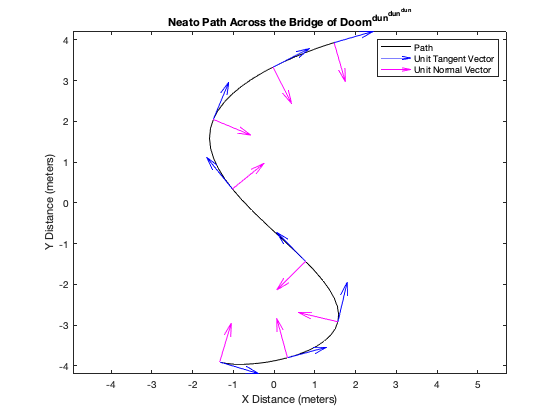

figure(1); clf;

points = double(subs(r, t, ts));
plot(points(:, 1), points(:, 2), 'k-'); axis equal; hold on;

ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / 6)';
start_points_for_arrows = double(subs(r, t, ts_for_arrows));
that_end_points = double(subs(T_hat, t, ts_for_arrows));
nhat_end_points = double(subs(N_hat, t, ts_for_arrows));
quiver(start_points_for_arrows(:, 1), start_points_for_arrows(:, 2), that_end_points(:, 1), that_end_points(:, 2), "off", 'filled', 'b');
quiver(start_points_for_arrows(:, 1), start_points_for_arrows(:, 2), nhat_end_points(:, 1), nhat_end_points(:, 2), "off", "filled", 'm');
legend("Path", "Unit Tangent Vector", "Unit Normal Vector")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)");
title("Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Exercise 21.2

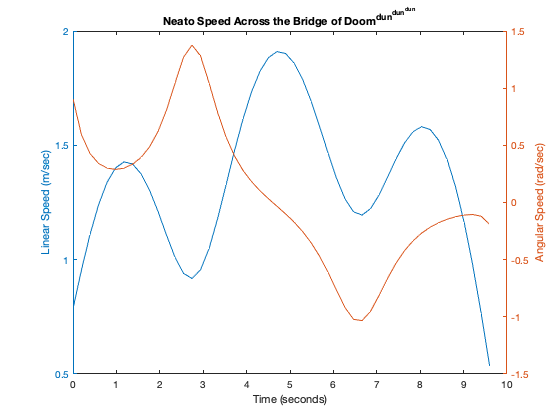

speeds = double(subs(speed, t, ts));
rot_speeds = double(subs(rotation_speed, t, ts));
figure(2); clf;
yyaxis left;
plot(ts, speeds);
ylabel("Linear Speed (m/sec)");
yyaxis right;
plot(ts, rot_speeds);
%legend("Linear Speed", "Angular Speed")
xlabel("Time (seconds)");
ylabel("Angular Speed (rad/sec)");
title("Neato Speed Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Exercise 21.3

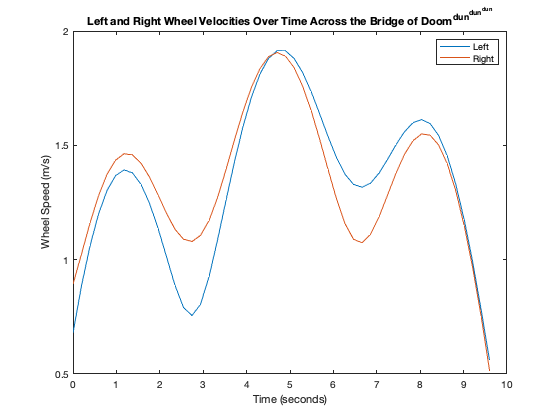

figure(3); clf;
v_ls = double(subs(v_l, t, ts));
v_rs = double(subs(v_r, t, ts));
plot(ts, v_ls); hold on;
plot(ts, v_rs);

title("Left and Right Wheel Velocities Over Time Across the Bridge of Doom^{dun^{dun^{dun}}}")
xlabel("Time (seconds)");
ylabel("Wheel Speed (m/s)");
legend("Left", "Right")

## Don't need any of this


%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
% B_hat=simplify(cross(T_hat,N_hat))
% 
% %We can also find the curvature
% kappa=norm(dT_hat)/norm(dr);
% kappa=simplify(kappa)
% 
% %How about the Torsion? 
% tau=-dot(N_hat,(diff(B_hat,t)/norm(dr)))
% a_N = simplify(dot(a, N_hat))
% a_T = simplify(dot(a, T_hat))

d = 0.235; % m
R = 1; % m
t_complete = 30; % s, time to complete a circle
w = (2 * pi) / t_complete

w = 0.2094

v_l_actual = double(subs(v_l)) % m/s

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

Error in sym/double (line 709)
        Xstr = mupadmex('symobj::double', S.s, 0);

v_r_actual = double(subs(v_r)) % m/s

%% Print everything nicely labeled for screenshotting
tangent_vector = dr
unit_tangent_vector = T_hat
linear_velocity_vector = v
disp("As opposed to the circle, the scalar coefficients on are different for each dimension.")
unit_normal_vector = N_hat
angular_velocity_vector = omega
fprintf("As compared to the circle, the angular velocity vector is *way* more complicated to\nreflect the fact that elptical motion involves a constantly changing rotational speed")
left_wheel_velocity = v_l
right_wheel_velocity = v_r

## Graphs

a = 3.2;
b = 2.2;
w = 1.3; % alpha
d = 0.235; % m

ts = linspace(0, 2 * pi / w, 50);

% NB: If this section complains about too many input arguments, rerun the
% first section and don't worry about it.

calc_r = matlabFunction(subs(r));
all_rs = reshape([calc_r(ts), zeros(1, 49)], [50 3]);
xlims = [min([-1; all_rs(:, 1)]), max([1; all_rs(:, 1)])] * 1.25;
ylims = [min([-1; all_rs(:, 2)]), max([1; all_rs(:, 2)])] * 1.25;
zlims = [min([-1; all_rs(:, 3)]), max([1; all_rs(:, 3)])] * 1.25;

old_t = t;
for t_cur=ts
    t = t_cur;
    r_cur = double(subs(r));
     v_cur = double(subs(v));
     omega_cur = double(subs(omega));
     
     figure(1); clf; 
     plot3_sane(all_rs(ts <= t, :), 'k-'); hold on; grid on;
     plot3_sane(r_cur, '.');
     quiver3_sane(r_cur, v_cur, 'b');
     quiver3_sane(r_cur, omega_cur, 'g');
     legend(["Path", "Current Position", "Linear Velocity", "Angular Velocity"])
     xlim(xlims); ylim(ylims); zlim(zlims);
     drawnow;
    hold off;
end
t = old_t;

figure(2); clf;

calc_v_l = matlabFunction(subs(v_l));
calc_v_r = matlabFunction(subs(v_r));

plot(ts, calc_v_l(ts)); hold on;
plot(ts, calc_v_r(ts));
xlabel("Time (s)")
ylabel("Wheel Velocity (m/s)")
title("Wheel Velocities Over Time")
legend("Left", "Right")
hold off;

function quiver3_sane(start, len, style)
    quiver3(start(:, 1), start(:, 2), start(:, 3), len(:, 1), len(:, 2), len(:, 3), style);
end

function plot3_sane(points, style)
    plot3(points(:, 1), points(:, 2), points(:, 3), style)
end
